%Testing for parabola function
%Luis Mario Bres Castro
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/SDMBIGDAT19-master/CODES'
addpath ../Func&data


%% Test harness for CRCBPSO using the first example
% The fitness function called is CRCBPSOTESTParabola. 
ffparams = struct('rmin',-100,...
                     'rmax',100 ...
                  );
% Fitness function handle.
fitFuncHandle = @(x) crcbpsotest_parabola(x,ffparams);
%%
% Call PSO.
nDim=100;
P = struct('popSize',40,... % Number of particles
           'maxSteps',4000,... % Number of steps
           'boundaryCond',[],...
           'nbrhdSz',[]...
          );
rng('default')
psoOut = crcbpso(fitFuncHandle,nDim);

%% Estimated parameters
% Best standardized and real coordinates found.
stdCoord = psoOut.bestLocation;
[~,realCoord] = fitFuncHandle(stdCoord);
disp(['Best location:',num2str(realCoord)]);

Best location:-4.40329     -1.57093      2.22485     -10.6936     -3.49535     -6.79466    0.0487274      13.0828      10.6297     0.795127      1.95867     -1.30276     -8.77736     -8.83654     -1.67453     -2.21085      10.3058      13.0504     -4.99461    -0.133947     -9.74937      -3.0239      4.24515     -5.22297      -1.7803     -1.41705     -1.32255      20.0714      4.02283    -0.712979      5.33369       9.3924      12.9031      8.95909      13.9792      22.4162      12.2782      5.64154     -4.50835     -9.38873     -16.9895     -5.03959      4.20192      4.81705     -1.71826      4.33393      19.7392      17.8367      7.33163     -1.27085     -12.6672     -3.92361      8.84524      -22.985      19.8478      7.55653     -1.32734      5.47779     -10.3343      -5.6078      29.0361      18.7466      6.04822     -4.78501      16.5353      18.3815     -9.86642      -9.3017     -14.1195      8.69824     -12.1224      14.9081      27.0601      24.4928     -2.97673      23.0574   

disp(['Best fitness:', num2str(psoOut.bestFitness)]);

Best fitness:12068.01


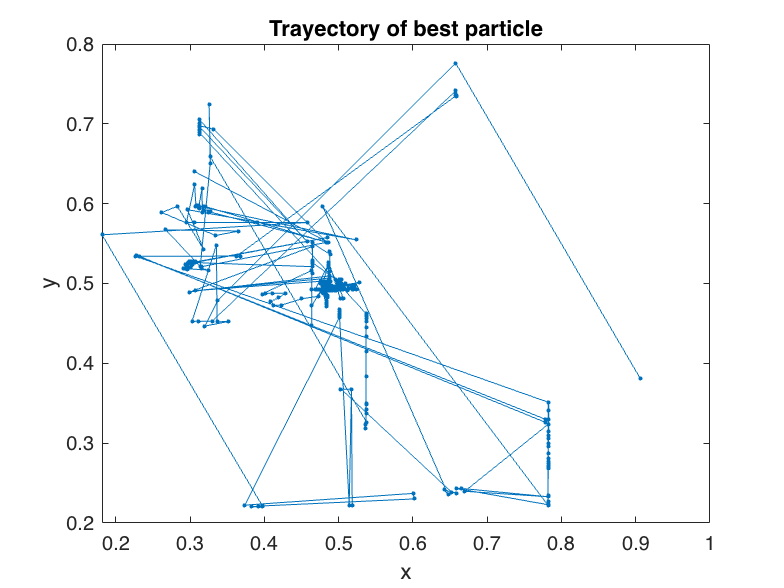


%%
% Call PSO with optional inputs
rng('default')
psoOut = crcbpso(fitFuncHandle,nDim,P,2);
%Plot the trajectory of the best particle
figure;
plot(psoOut.allBestLoc(:,1),psoOut.allBestLoc(:,2),'.-');
title('Trayectory of best particle')
xlabel('x')
ylabel('y')

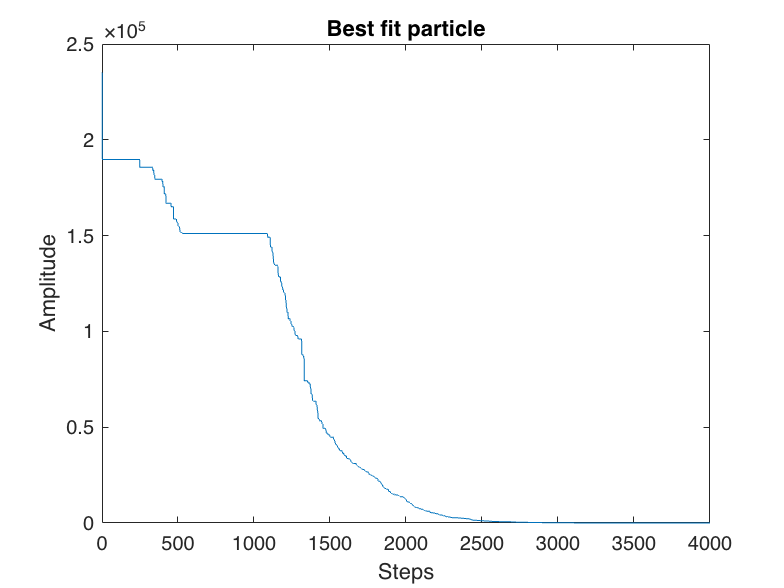

figure;
plot(psoOut.allBestFit);
title('Best fit particle')
xlabel('Steps')
ylabel('Amplitude')

clear
%%% Test harness for CRCBPSO using the second example
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/SDMBIGDAT19-master/CODES'
addpath ../Func&data

P = struct('popSize',40,... % Number of particles
           'maxSteps',4000,... % Number of steps
           'boundaryCond',[],...
           'nbrhdSz',[]...
          );
%% Test harness for CRCBPSO 
% The fitness function called is CRCBPSOTESTFUNC. 
ffparams = struct('rmin',-100,...
                     'rmax',100 ...
                  );
% Fitness function handle.
fitFuncHandle = @(x) crcbpsotest_parabola(x,ffparams);
%%
% Dimensionality of the search space
nDim = 30;

% Call PSO and use best-of-M-runs
nRuns = 10; %Number of PSO runs
psoOut = struct('totalFuncEvals',[],...
                    'bestLocation',zeros(1,nDim),...
                    'bestFitness',[]);
%We need to have one psoOut struct for each run: make a struct array with
%each element initialized to be the same as the first
for lpruns = 2:nRuns
    psoOut(lpruns) = psoOut(1);
end
parfor lpruns = 1:nRuns
        %Reset random number generator for each worker such that the
        %pseudo-random sequence is different for them but they repeat
        %everytime this code is run
        rng(lpruns);
        %PSO run 
        psoOut(lpruns) = crcbpso(fitFuncHandle,nDim,P);

end
%Find best run
bestRun = 1;
for lpruns = 2:nRuns
    if psoOut(lpruns).bestFitness < psoOut(bestRun).bestFitness
        bestRun = lpruns;
    end
end
%% Estimated parameters
% Best standardized and real coordinates found.
stdCoord = psoOut(bestRun).bestLocation;
[~,realCoord] = fitFuncHandle(stdCoord);
disp(['Best run:',num2str(bestRun)]);

Best run:6


disp(['Best location:',num2str(realCoord)]);

Best location:1.5518e-10  1.6651e-10  3.8696e-11 -1.7903e-10  4.0927e-11  1.0854e-10  2.9331e-11  9.0353e-11 -2.3797e-10  4.0103e-11 -6.9605e-11 -7.0514e-11  1.7928e-10 -3.4646e-11  1.0851e-10  6.1988e-11  6.1064e-11 -3.7375e-11 -6.8241e-11  2.3164e-11  5.1912e-11  1.0712e-10   1.238e-10  1.6685e-10 -1.3138e-10 -1.0853e-10  -1.377e-10 -6.0609e-11  1.0058e-10  1.5007e-11


disp(['Best fitness:', num2str(psoOut(bestRun).bestFitness)]);

Best fitness:3.5453e-19


disp('Info for all runs:');

Info for all runs:


for lpruns = 1:nRuns
    stdCoord = psoOut(lpruns).bestLocation;
    [~,realCoord] = fitFuncHandle(stdCoord);
    disp(['Best location for run ',num2str(lpruns),': ',num2str(realCoord)]);
    disp(['Best fitness for run ',num2str(lpruns),': ', num2str(psoOut(lpruns).bestFitness)]);
    disp('*****************');
end

Best location for run 1: 9.2882e-11 -7.4607e-11  1.1191e-10 -3.7161e-11 -4.8516e-11  9.8197e-12  7.7989e-11  4.9866e-11  1.0336e-10 -9.6989e-11  6.0567e-11  2.8265e-11  6.9065e-12  1.3927e-12 -1.7926e-10  2.8109e-11  7.4323e-12  2.5446e-10 -7.2973e-11  1.5015e-10  1.2155e-10  8.7127e-11 -5.6176e-11 -4.5475e-12 -2.3988e-11 -4.3973e-10 -2.4421e-10 -4.2121e-11 -9.4786e-12 -2.6631e-10


Best fitness for run 1: 5.4122e-19


*****************


Best location for run 2: 5.4271e-11  1.2162e-10 -1.3074e-12  -3.907e-10  3.8369e-12 -6.0226e-11  1.2832e-11  -1.605e-10  -2.107e-10 -1.3978e-10 -1.0301e-10   2.378e-10 -1.5248e-11  8.6203e-11 -6.0268e-11  5.2623e-11 -6.1576e-11  1.8588e-10 -1.0886e-11 -8.5549e-11 -7.2077e-11  2.0948e-10 -1.3962e-10  3.2223e-10  6.5441e-11  -7.951e-11  2.0378e-11 -2.6156e-10 -2.3135e-10  1.9782e-11


Best fitness for run 2: 6.9665e-19


*****************


Best location for run 3: -2.6212e-10 -6.5199e-11 -2.2297e-11 -6.3523e-11  2.9601e-11 -1.6843e-10 -1.6141e-10  5.7092e-10  2.6981e-10  1.4178e-10 -9.0552e-11   1.196e-10 -1.1151e-10 -4.6077e-10  2.6017e-10 -8.0703e-11 -2.6546e-11  2.7151e-10 -4.1739e-10 -6.8596e-11  3.3518e-10  2.4158e-10 -3.5556e-10 -1.6563e-10  7.2788e-11  3.3702e-10  3.2804e-10  1.0169e-10 -3.0724e-10 -3.7043e-10


Best fitness for run 3: 1.9194e-18


*****************


Best location for run 4: 4.3352e-10 -2.3125e-10 -2.7602e-10  1.7961e-10  2.0322e-11  4.3184e-10 -1.6045e-10 -2.0378e-11 -2.6795e-10  1.3856e-11 -2.9502e-10  3.6987e-10  1.5912e-10 -5.7739e-11  8.6693e-10  1.8744e-11 -5.5607e-11 -8.2991e-11  2.9678e-10  2.2918e-10 -1.9699e-10  3.0511e-11  6.4604e-10 -2.3678e-10  1.8304e-10 -2.2044e-10 -7.5431e-11  2.6603e-11 -3.6806e-12 -5.3389e-10


Best fitness for run 4: 2.6766e-18


*****************


Best location for run 5: -1.2484e-10 -8.5686e-10 -2.8166e-11 -3.4555e-10  7.0574e-10 -1.1469e-09  3.1044e-10 -4.1797e-10  1.4447e-10 -3.4628e-10  4.2269e-10  1.2747e-11  -2.337e-10 -4.3114e-10  8.8924e-10 -2.0339e-10 -1.7735e-11 -4.1467e-11  1.2542e-09  4.9999e-10 -6.8229e-10  -8.106e-10 -4.4437e-10  -6.001e-10 -6.9008e-11  1.8497e-10 -2.5473e-10 -5.2208e-10 -1.0479e-09  1.4842e-10


Best fitness for run 5: 9.3484e-18


*****************


Best location for run 6: 1.5518e-10  1.6651e-10  3.8696e-11 -1.7903e-10  4.0927e-11  1.0854e-10  2.9331e-11  9.0353e-11 -2.3797e-10  4.0103e-11 -6.9605e-11 -7.0514e-11  1.7928e-10 -3.4646e-11  1.0851e-10  6.1988e-11  6.1064e-11 -3.7375e-11 -6.8241e-11  2.3164e-11  5.1912e-11  1.0712e-10   1.238e-10  1.6685e-10 -1.3138e-10 -1.0853e-10  -1.377e-10 -6.0609e-11  1.0058e-10  1.5007e-11


Best fitness for run 6: 3.5453e-19


*****************


Best location for run 7: 1.0422e-09  1.4224e-10 -5.8897e-10  2.3661e-10 -1.0881e-09  1.3047e-10 -3.1054e-10  1.7381e-10  -1.548e-10  5.5775e-10  2.1485e-10  2.3176e-10  1.7346e-10   3.526e-10  -4.419e-10 -3.3984e-10  1.1211e-09 -2.0634e-10 -3.6763e-10 -9.1627e-10   4.832e-10 -7.9083e-11  2.9092e-10 -2.3127e-10 -8.1315e-11 -6.0456e-10  3.2254e-10  3.4395e-10 -6.0693e-10 -1.5176e-10


Best fitness for run 7: 7.3747e-18


*****************


Best location for run 8: -2.1903e-10 -2.8788e-10  1.4913e-10  5.7081e-10  1.9485e-10  1.0412e-10 -4.8033e-12 -1.4822e-11 -4.6126e-10   1.257e-10 -7.7819e-11 -4.1589e-10  2.8575e-10  1.6982e-11 -6.5033e-10 -1.7009e-10 -2.6913e-10  7.5005e-11 -6.7985e-11  6.7624e-10 -7.6113e-11   1.933e-10 -2.7664e-10 -3.5625e-10  1.4633e-10  9.8778e-10 -3.4575e-11 -3.5286e-10  1.5913e-10 -1.0121e-10


Best fitness for run 8: 3.4143e-18


*****************


Best location for run 9: 2.3321e-10 -2.9529e-10  3.7352e-10  -5.802e-10 -2.4716e-10  1.2193e-11  2.9412e-10 -1.0319e-10 -3.7211e-10   1.431e-10 -1.1245e-10  2.1828e-11 -1.1113e-10  2.6637e-10 -3.6752e-10 -2.0883e-10 -1.4001e-10 -2.5662e-10  2.3891e-10 -2.2176e-10 -2.9929e-10 -7.3477e-10  8.5535e-11 -9.9817e-11 -2.3775e-11  1.2751e-10  1.7882e-10  1.7464e-10  1.3671e-11 -6.9491e-12


Best fitness for run 9: 2.1282e-18


*****************


Best location for run 10: 1.5233e-10  1.1721e-10 -6.0903e-10   9.004e-11  6.0179e-10  1.3311e-09 -1.0047e-09  7.2318e-10 -1.2452e-10  5.8944e-10  6.6575e-10 -6.3966e-10  7.7307e-10 -1.2719e-11 -1.8311e-10  1.3843e-10  6.6743e-10 -8.6328e-10   5.594e-10  -5.282e-10  5.2025e-10  1.1828e-10  6.6731e-10  3.4565e-10 -6.4723e-10   9.552e-10 -4.2093e-11  1.6244e-10  1.8716e-11  3.4484e-10


Best fitness for run 10: 1.0059e-17


*****************
